# Project 2 by Connor Nguyen (UHid: 1787501)

## Excercise 5

### a)

127/13+pi

ans = 12.9108

exp(3)*13i

ans = 0.0000e+00 + 2.6111e+02i

exp(pi*i)

ans = -1.0000 + 0.0000i

### b)

C = [0.5; 2; 1];
B = [2 3 2; -0.25 0 -1; 3/5 -3/5 0];
C*C'

ans =     0.2500    1.0000    0.5000
    1.0000    4.0000    2.0000
    0.5000    2.0000    1.0000


C'*B*C

ans = 1.3500

### c)

23+10^37+1000-10^37

ans = 0

by hand we will result in 1023, but matlab did not capture it

## Excercise 6

### a)

norm(C)

ans = 2.2913

mean(C)

ans = 1.1667

### b)

det(B)

ans = -2.7000

inv(B)

ans =     0.2222    0.4444    1.1111
    0.2222    0.4444   -0.5556
   -0.0556   -1.1111   -0.2778


### c)

[V,D]=eig(B)

V =    -0.8005   -0.7550   -0.7251
    0.4002    0.4462    0.3626
   -0.4462   -0.4805    0.5854


D =     1.6147         0         0
         0    1.5000         0
         0         0   -1.1147


## Excerise 7

A = magic(5)

A =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


A(:,4)

ans =      8
    14
    20
    21
     2


A(2:4,2:4)

ans =      5     7    14
     6    13    20
    12    19    21


A(1:2:5,:)

ans =     17    24     1     8    15
     4     6    13    20    22
    11    18    25     2     9


A(2,:)

ans =     23     5     7    14    16


A(3,5)

ans = 22

A([1,5],[1,5])

ans =     17    15
    11     9


## Excercise 8

a=5;b=2;c=-1;

a < 10 & a > 0

ans = logical
   1


abs(c)-b/2>0

ans = logical
   0


b == a + 3*c

ans = logical
   1


c~=-1

ans = logical
   0


a < 4 | ( c <= 2 & b>2 )

ans = logical
   0


## Excercise 9

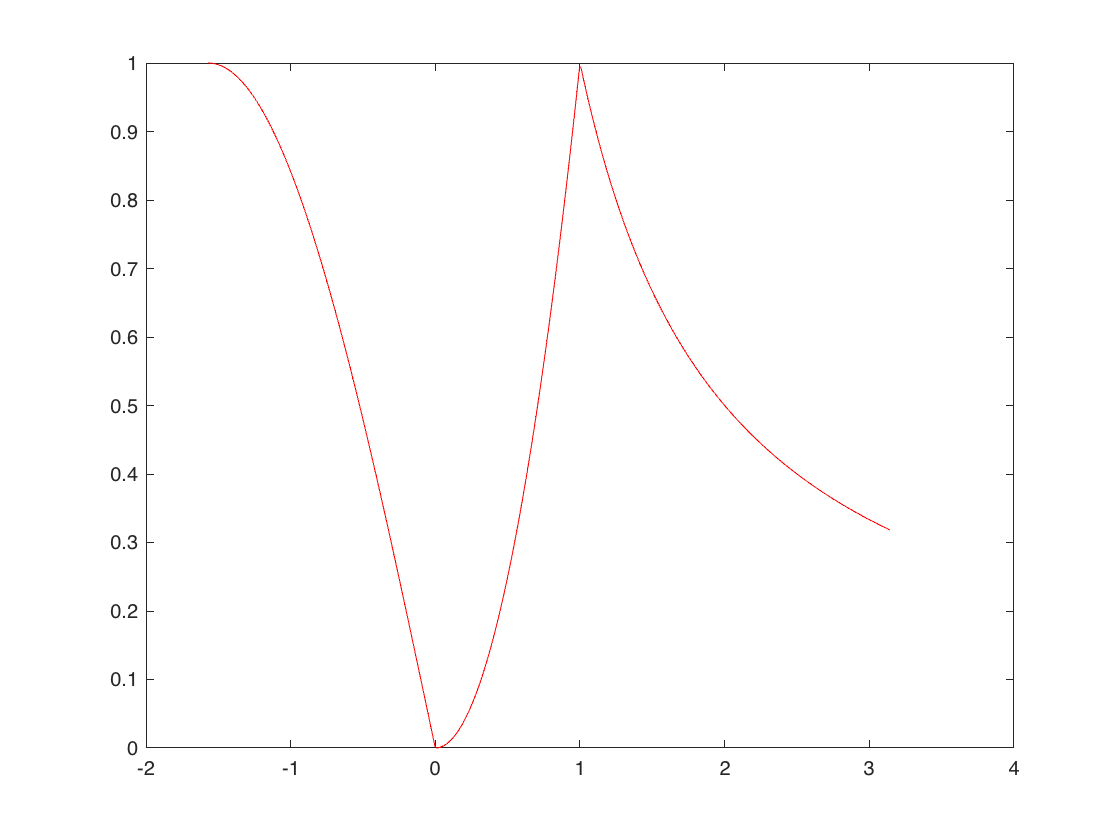

x=linspace(-pi/2,pi,500);
y=f_stk(x);
plot(x,y,'-r')

## Excercise 10

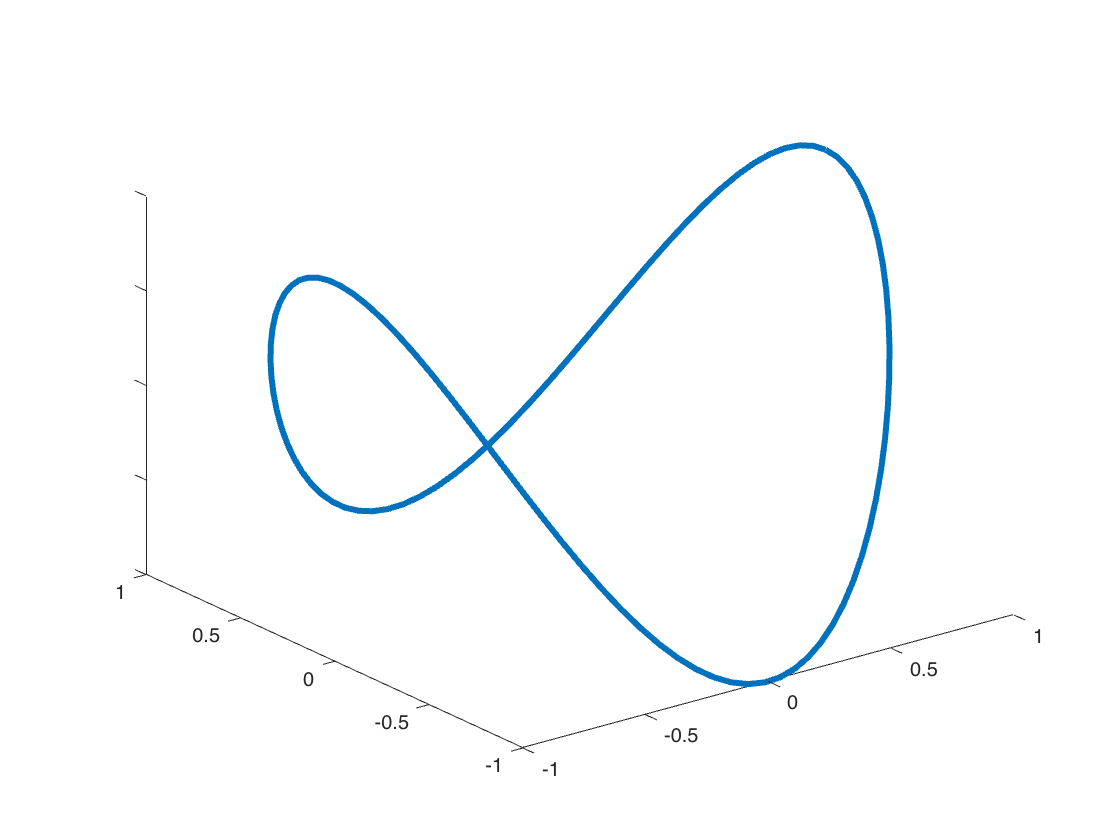

t=linspace(0,2*pi,100);
plot3(cos(t),sin(t),cos(2*t),'LineWidth',3)

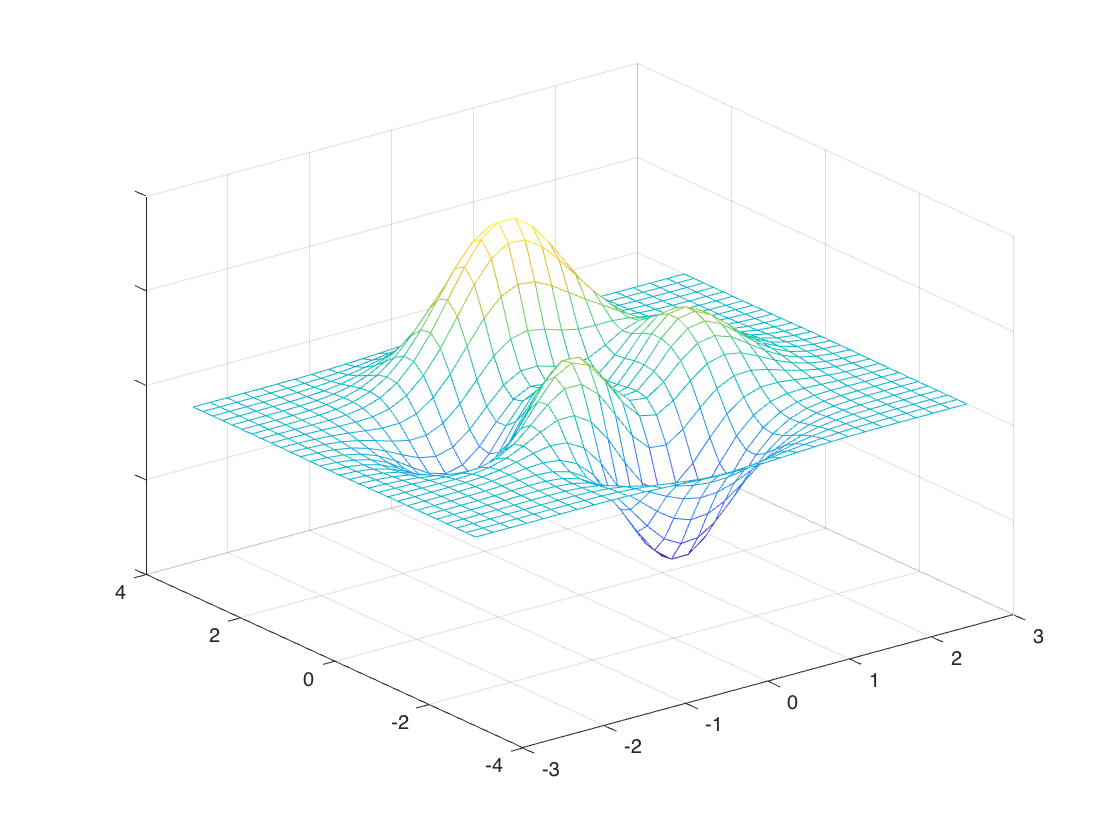

[X,Y,Z] = peaks(30);
mesh(X,Y,Z)

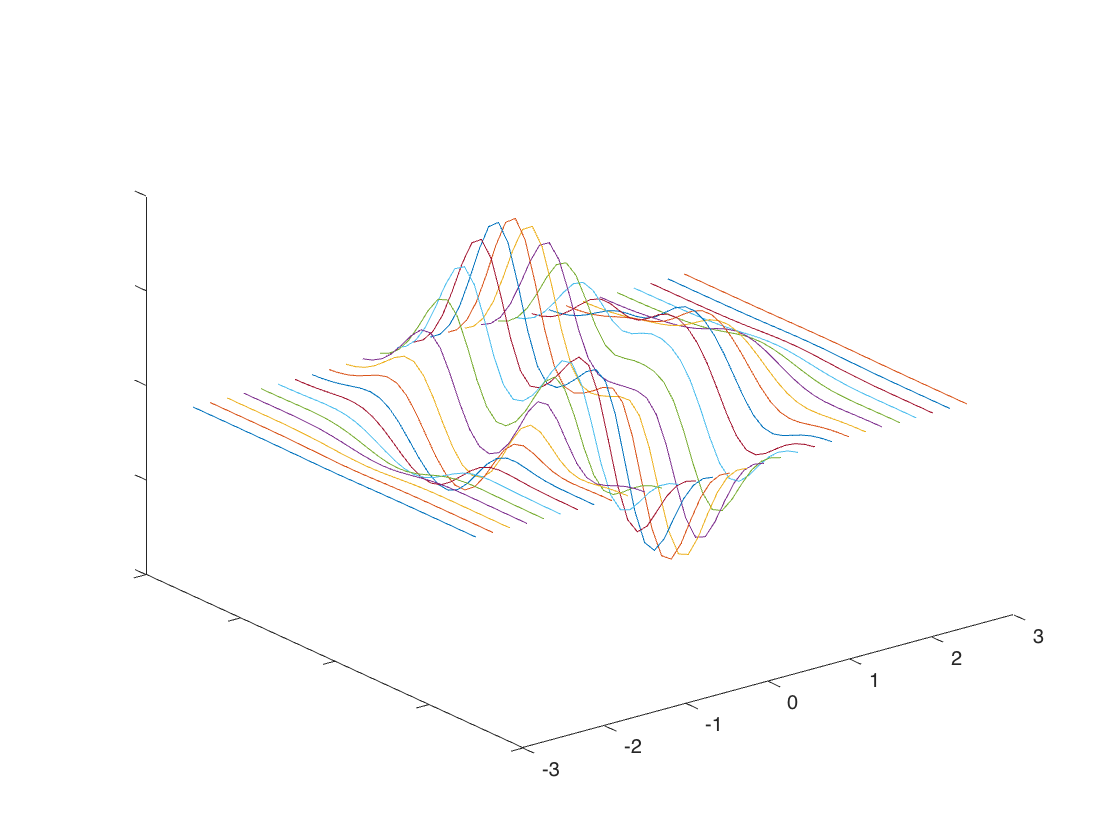

plot3(X,Y,Z)

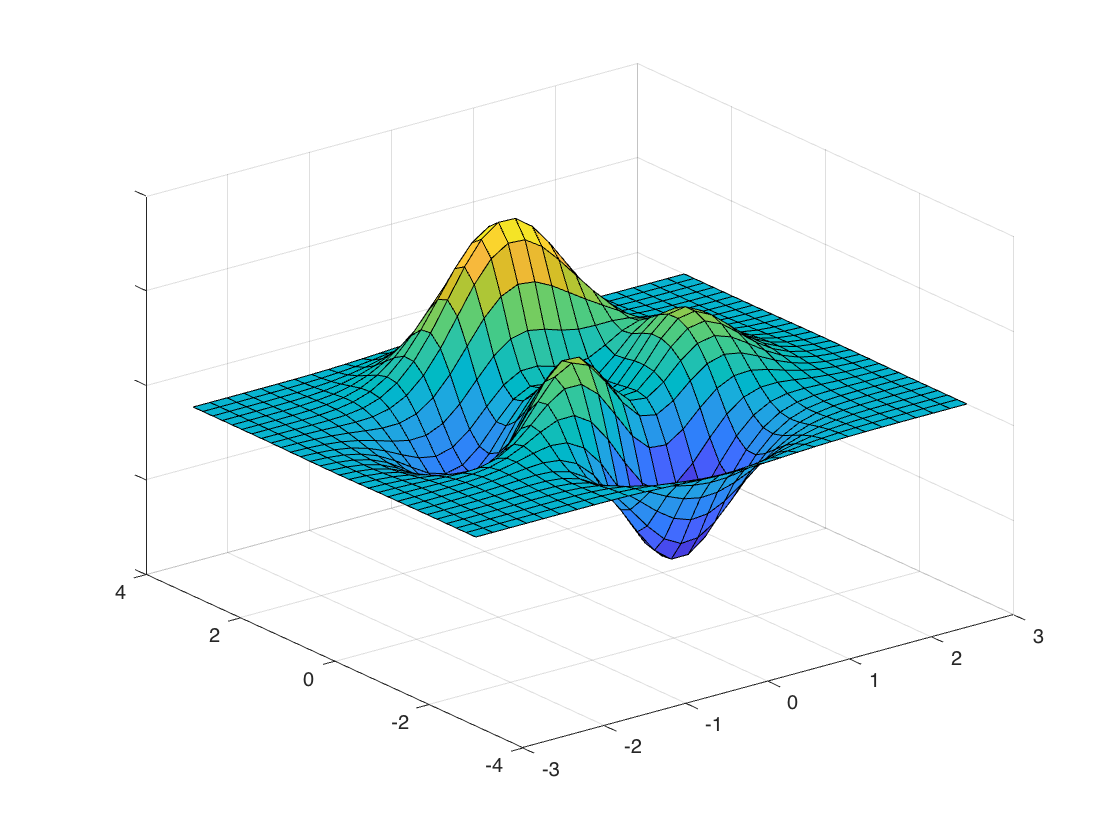

surf(X,Y,Z)

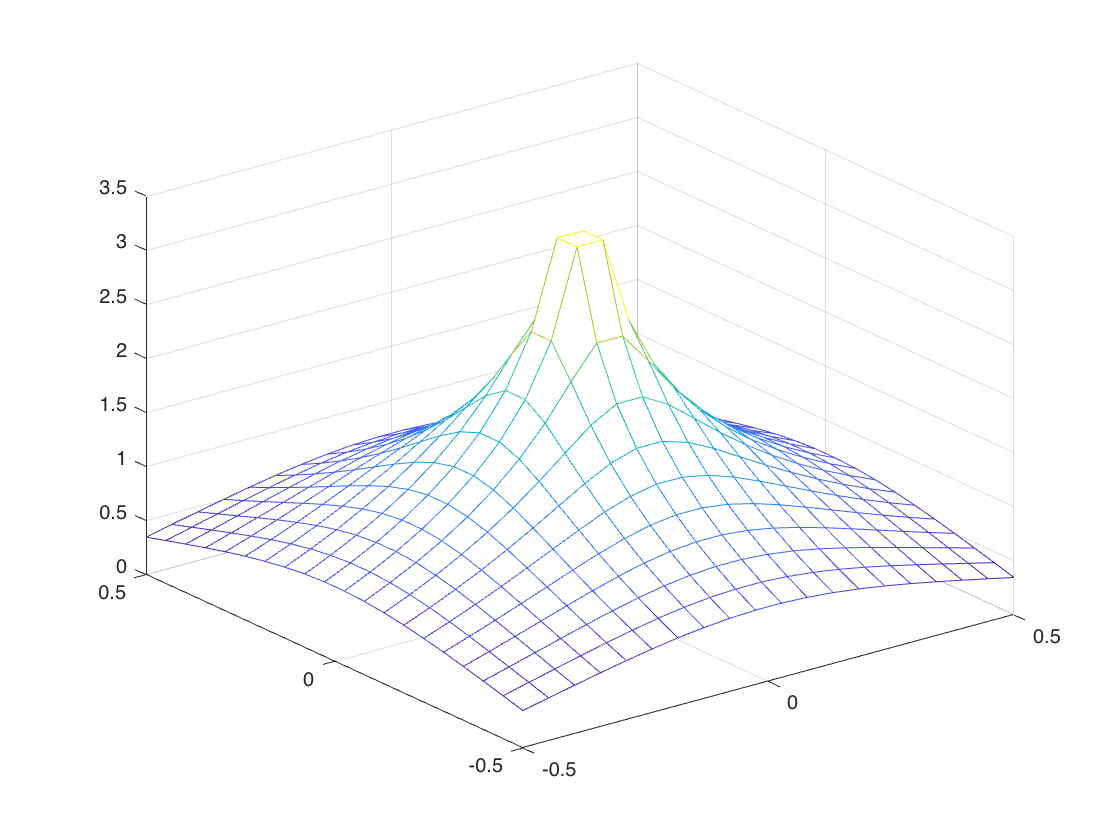

x = linspace(-0.5,0.5,20);
[X,Y] = meshgrid(x,x);
Z = log(1./sqrt(X.^2+Y.^2)); 
mesh(X,Y,Z)

## Excercise 11

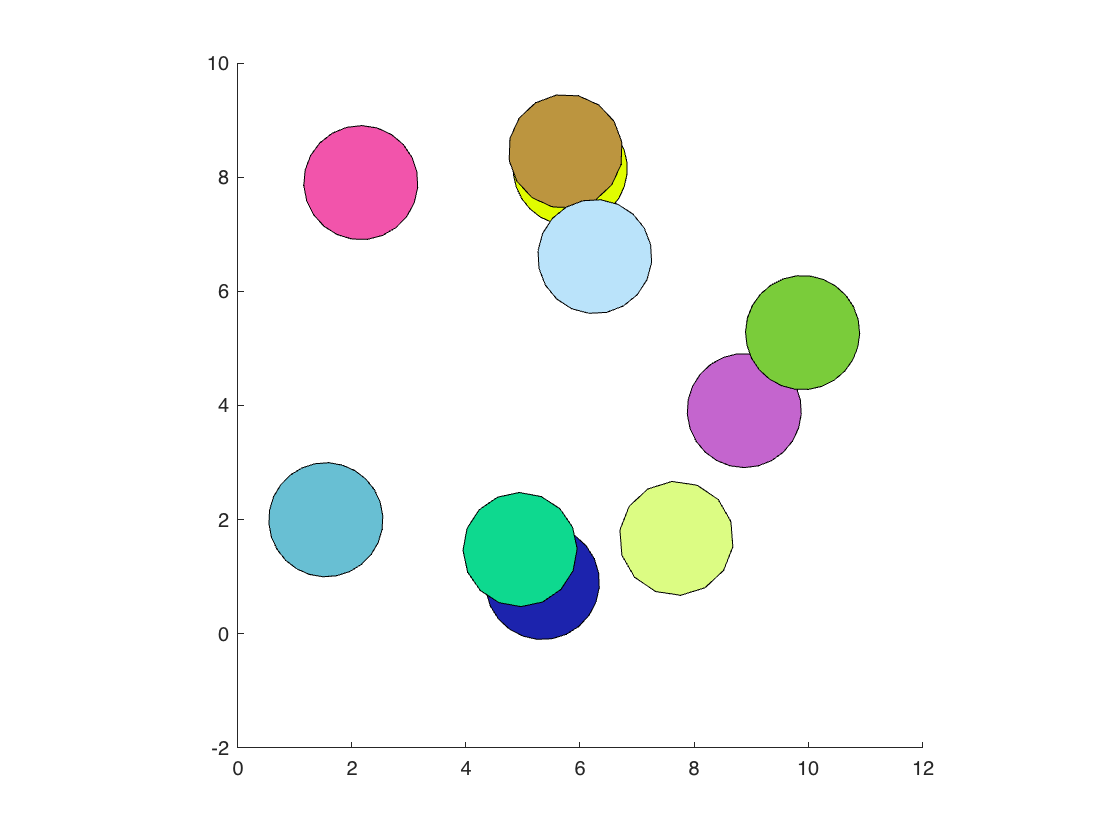

clear all; close all
n_ecke(10)

## Excercise 12

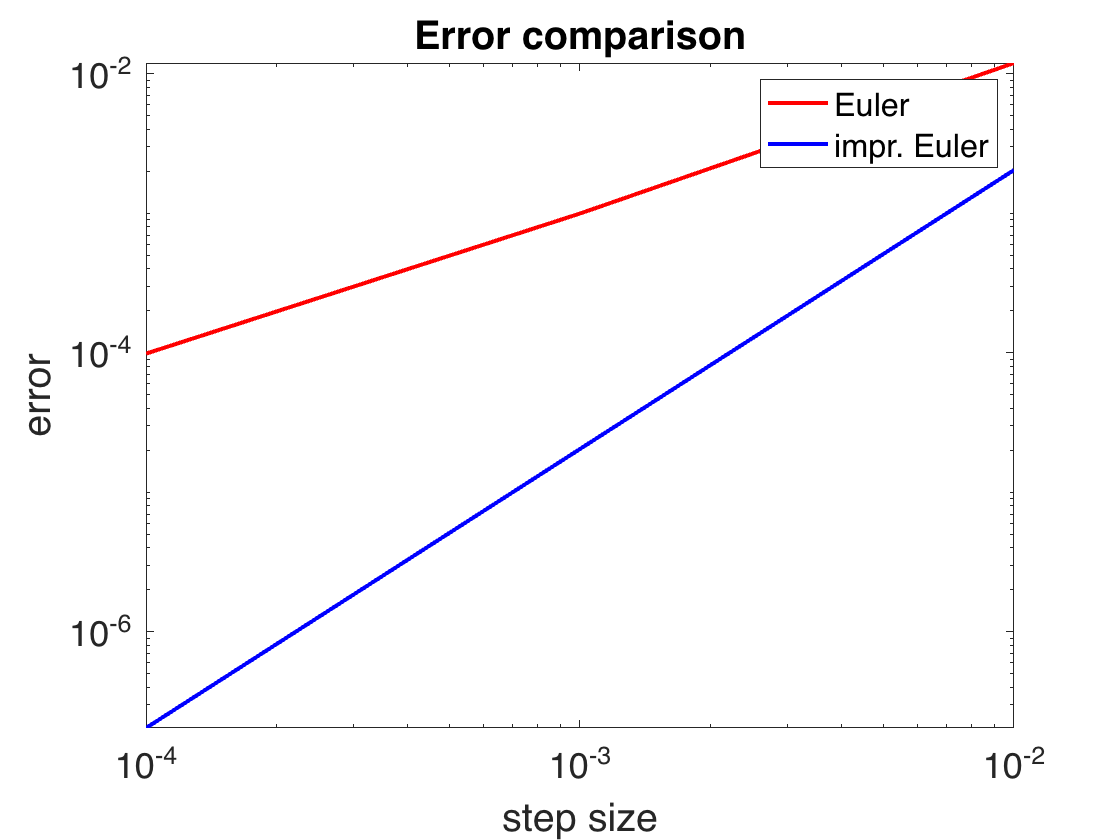

% clear all variables and plot windows
clear all; close all;

% set parameter
l = 0.1;       % length of pendulum
g = 9.81;      % gravitational constant

% write the variables into the field var
var = [l, g];

% set time interval
t0 = 0.0;
T = 2*pi*sqrt(l/g);

% initial conditions
x0 = [0.05; 0];
d = length(x0);
% exact solution
xex = x0;
maxstep = 3;
% create stepsize and error vectors
hvec = zeros(1,maxstep);
erreuler = zeros(1,maxstep);
errimpreuler = zeros(1,maxstep);

% loop on different number of time steps
for i=1:maxstep
    n = 10^(1+i);
    
    % define the output variables
    tvec = zeros(1,n+1);
    xeuler = zeros(d,n+1);
    ximpreuler = zeros(d,n+1);
    
    % call the solvers
    [tvec, xeuler] = EULER(@LINEARPENDULUMODE, t0, T, x0, n, var);
    [tvec, ximpreuler] = IMPR_EULER(@LINEARPENDULUMODE, t0, T, x0, n, var);
    
    % compute the error
    hvec(i) = 1/n;
    erreuler(i) = norm(xeuler(:,end)-xex);
    errimpreuler(i) = norm(ximpreuler(:,end)-xex);
end
    
% create plot
figure(1);
loglog(hvec,erreuler,'r-','Linewidth',2);
hold on; 
title('Error comparison','FontSize',18);
xlabel('step size','FontSize',18);
ylabel('error','FontSize',18);
set(gca,'FontSize',18);
loglog(hvec,errimpreuler,'b-','Linewidth',2);
legend('Euler','impr. Euler');

## Excercise 13

### a)


$$\textrm{let}\;\chi \;\textrm{be}\;\textrm{the}\;\textrm{root}\;\textrm{of}\;\textrm{the}\;\textrm{equation}\;x^3 +4x^2 -10=0$$


consider

i) ${\;\phi }_1 \left(\chi \right)=\chi -\left(\chi^3 +4*\chi^2 -10\right)=\chi$ $\Rightarrow \chi \;\textrm{is}\;\textrm{the}\;\textrm{fix}\;\textrm{point}\;\textrm{of}\;\phi_1$

ii) $\textrm{we}\;\textrm{have}\;\chi^3 +4\chi^2 -10=0\;\to \chi^2 =\frac{\left(10-\chi^3 \right)}{4}\;\to \chi =\sqrt{\left(\left(\frac{\left(10-\chi^3 \right)}{4}\right)\right)}=\phi_2 \left(\chi \right)\to \chi \;\textrm{is}\;\textrm{the}\;\textrm{fixed}\;\textrm{point}\;\textrm{of}\;\phi_2$

iii) $\phi_3 \left(\chi \right)=\chi -\frac{\chi^3 +4*\chi^2 -10}{3{*\chi }^3 +8*\chi \;}=\chi \;\to \chi \;\textrm{is}\;\textrm{the}\;\textrm{fixed}\;\textrm{point}\;\textrm{of}\;\phi_3$

### b) Done in the function section

### c) 

clear all; close all;

% Examples for usage of fixed-point
phi_1 = inline('x-x.^3-4*x.^2+10');
phi_2 = inline('(1/2)*(10-x.^3).^(1/2)');
phi_3 = inline('x-((x.^3+4*x.^2-10)./(3*x.^2+8*x))');

fixed_point(phi_1, 1.5, 1e-5, 15);

 
The iteration did not converge within 15 iterations
The last two iterates are NaN and NaN


fixed_point(phi_2, 1.5, 1e-5, 15);

 
The iteration did not converge within 15 iterations
The last two iterates are 1.365224 and 1.365242


fixed_point(phi_3, 1.5, 1e-5, 15);

 
The procedure was successful after 4 iterations
The root to the equation is 1.365230


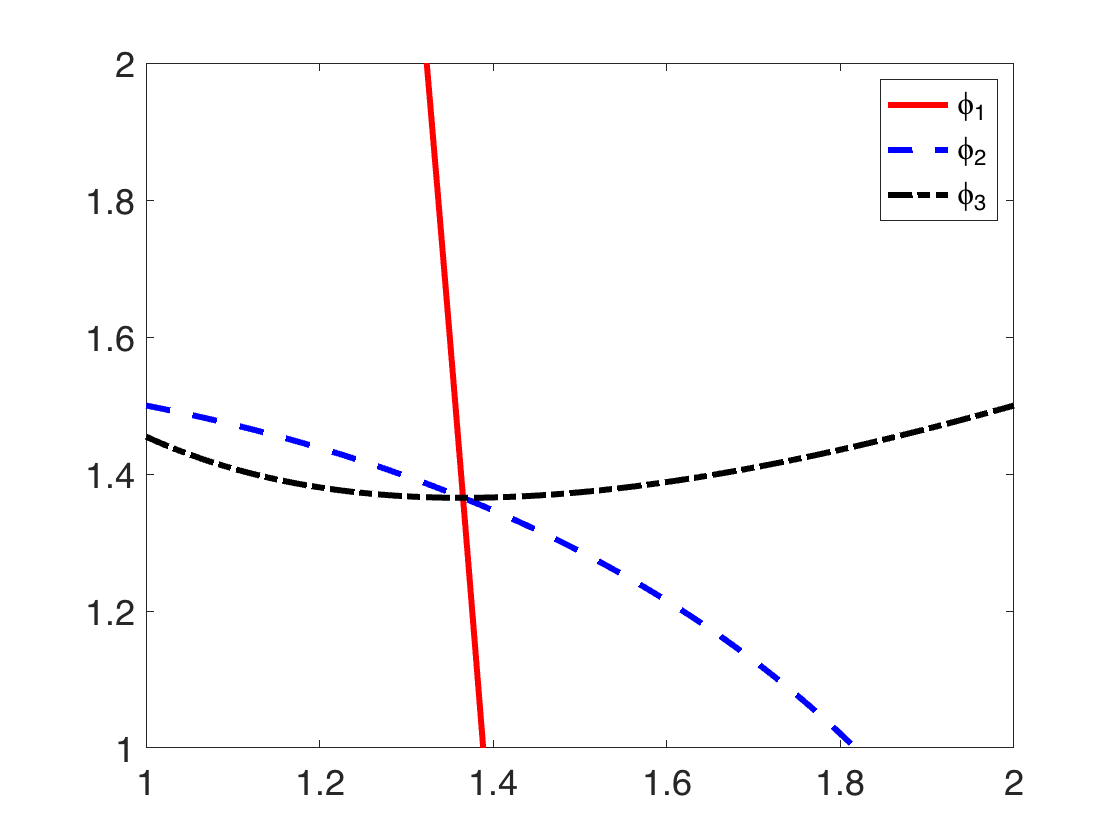


xvec = linspace(1,2,200);
plot(xvec,phi_1(xvec),'r-','LineWidth',3);
hold on;
plot(xvec,phi_2(xvec),'b--','LineWidth',3);
plot(xvec,phi_3(xvec),'k-.','LineWidth',3);
set(gca,'FontSize',18);
ylim([1 2]);
legend('\phi_1','\phi_2','\phi_3');

## Excercise 14

## a) Done in function tab

## b)

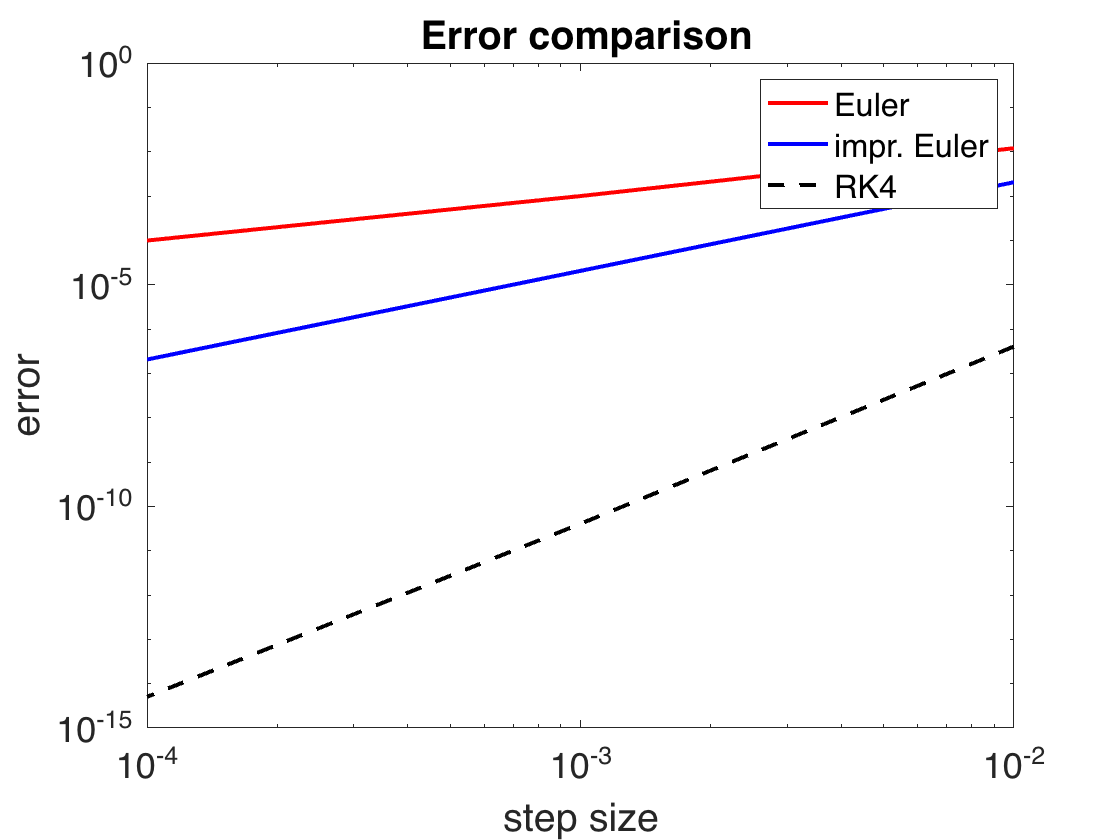

clear all ; close all ;
% set parameter
l = 0.1;
% length of pendulum
g = 9.81;
% gravitational constant

% write the variables into the field var
var = [l, g];
% set time interval
t0 = 0.0;
T = 2*pi*sqrt(l/g);
% initial conditions
x0 = [0.05; 0];
d = length(x0);
% exact solution
xex = x0;
maxstep = 3;
% create stepsize and error vectors
hvec = zeros(1,maxstep);
erreuler = zeros(1,maxstep); 
errimpreuler = zeros(1,maxstep); 
errrk4 = zeros(1,maxstep);
% loop on different number of time steps
for i =1:maxstep
    n = 10^(1+i);
    % define the output variables
    tvec = zeros(1,n+1);
    xeuler = zeros(d,n+1);
    ximpreuler = zeros(d,n+1);
    xrk4 = zeros(d,n+1);
    % call the solvers
    [tvec, xeuler] =EULER(@LINEARPENDULUMODE, t0, T, x0, n, var);
    [tvec, ximpreuler] =IMPR_EULER(@LINEARPENDULUMODE, t0, T, x0, n, var); 
    [ tvec , xrk4 ] = RK4class(@LINEARPENDULUMODE, t0 , T, x0 , n , var );
    % compute the error
    hvec(i) = 1/n;
    erreuler(i) =norm(xeuler(:,end)-xex); 
    errimpreuler(i) = norm(ximpreuler(: ,end)-xex);
    errrk4(i) =norm(xrk4(:,end)-xex);
end
% create plot
figure (1);
loglog(hvec , erreuler , 'r-' , 'Linewidth' ,2); 
hold on ;
title ( ' Error comparison' , 'FontSize' ,18); 
xlabel('step size', 'FontSize' ,18); 
ylabel( 'error' ,  'FontSize' ,18);
set(gca, 'FontSize',18);

loglog(hvec , errimpreuler , 'b-' , 'Linewidth' ,2);
loglog(hvec , errrk4 , 'k--' , 'Linewidth' ,2); 
legend('Euler','impr. Euler','RK4');

### c)

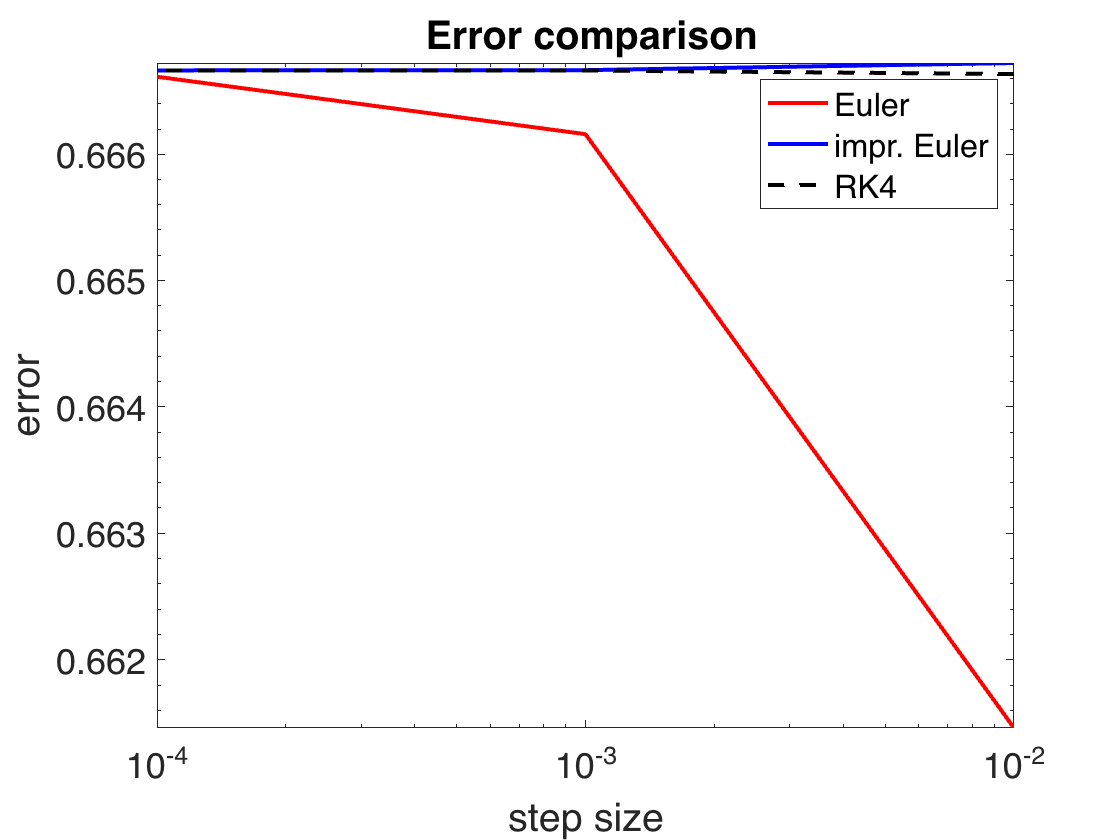

clear all ; close all ;
% set parameter
l = 0.1;
% length of pendulum
g = 9.81;
% gravitational constant

% write the variables into the field var
var = [l, g];
% set time interval
t0 = 0.0;
T = 1;
% initial conditions
x0 = 2/3;
d = length(x0);
% exact solution
xex = x0;
maxstep = 3;
% create stepsize and error vectors
hvec = zeros(1,maxstep);
erreuler = zeros(1,maxstep); 
errimpreuler = zeros(1,maxstep); 
errrk4 = zeros(1,maxstep);
% loop on different number of time steps
for i =1:maxstep
    n = 10^(1+i);
    % define the output variables
    tvec = zeros(1,n+1);
    xeuler = zeros(d,n+1);
    ximpreuler = zeros(d,n+1);
    xrk4 = zeros(d,n+1);
    % call the solvers
    [tvec, xeuler] =EULER(@RHSFUNC, t0, T, x0, n, var);
    [tvec, ximpreuler] =IMPR_EULER(@RHSFUNC, t0, T, x0, n, var); 
    [ tvec , xrk4 ] = RK4class(@RHSFUNC, t0 , T, x0 , n , var );
    % compute the error
    hvec(i) = 1/n;
    erreuler(i) =norm(xeuler(:,end)-xex); 
    errimpreuler(i) = norm(ximpreuler(: ,end)-xex);
    errrk4(i) =norm(xrk4(:,end)-xex);
end
% create plot
figure (1);
loglog(hvec , erreuler , 'r-' , 'Linewidth' ,2); 
hold on ;
title ( ' Error comparison' , 'FontSize' ,18); 
xlabel('step size', 'FontSize' ,18); 
ylabel( 'error' ,  'FontSize' ,18);
set(gca, 'FontSize',18);

loglog(hvec , errimpreuler , 'b-' , 'Linewidth' ,2);
loglog(hvec , errrk4 , 'k--' , 'Linewidth' ,2); 
legend('Euler','impr. Euler','RK4');

## Excercise 15

### a)

#### i) Explicit Euler


$$g\left(z\right)=1+z$$


#### ii) improve Euler


$$g\left(z\right)=1+z+\frac{z^2 }{2}$$


#### iii) Implicit Euler


$$g\left(z\right)=1+{z\left(1-z\right)}^{-1} \;\to g\left(z\right)=\frac{1}{1-z}$$


#### iv) Traperzoidal rule


$$\begin{array}{l}
\gamma^T =\left\lbrack \begin{array}{cc}
\frac{1}{2} & \frac{1}{2}
\end{array}\right\rbrack ,B=\left\lbrack \begin{array}{cc}
0 & 0\\
\frac{1}{2} & \frac{1}{2}
\end{array}\right\rbrack ,I-\textrm{zB}=\left\lbrack \begin{array}{cc}
1 & 0\\
-\frac{z}{2} & 1-\frac{z}{2}
\end{array}\right\rbrack ,\\
\to g\left(z\right)=1+z\;\left\lbrack \begin{array}{cc}
\frac{1}{2} & \frac{1}{2}
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
1 & 0\\
-\frac{z}{2} & 1-\frac{z}{2}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack \\
\to g\left(z\right)=\frac{1+\frac{z}{2}}{1-\frac{z}{2}}
\end{array}$$


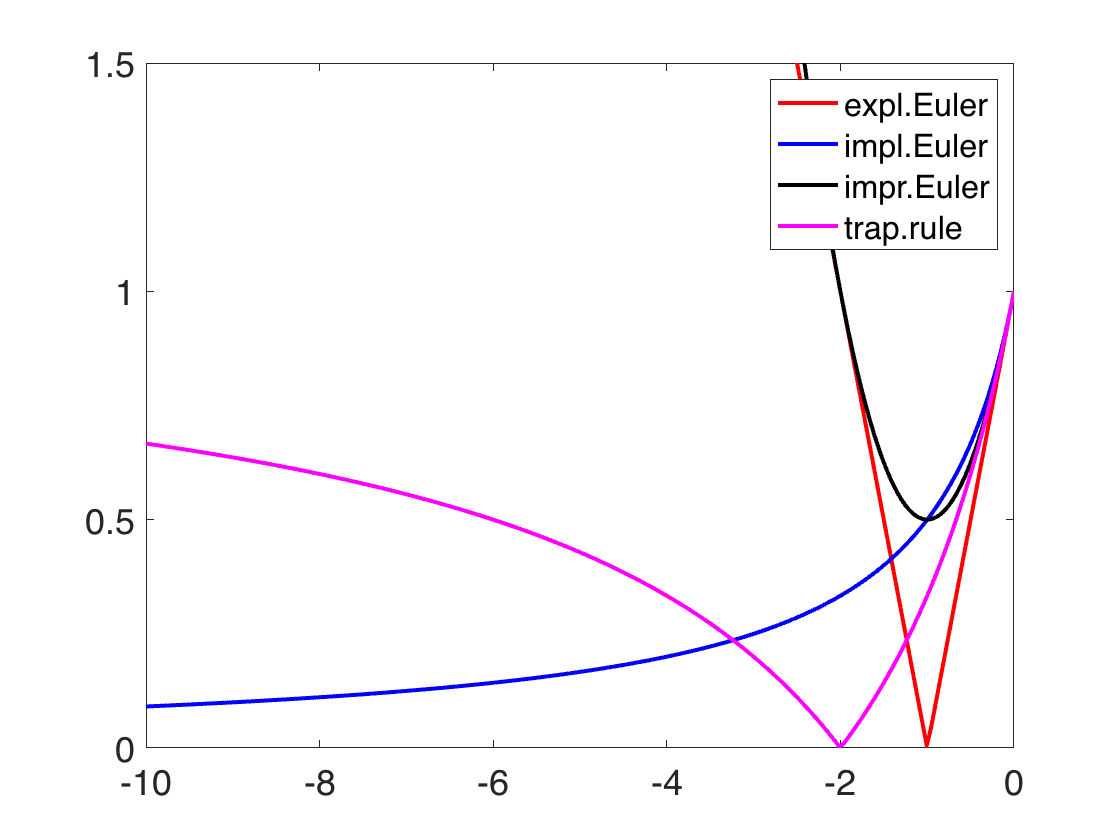

clear all ; close all ;
zvec = linspace(-10,0,200);
gEE = 1+zvec;
gIE = 1./(1-zvec);
gME = 1+zvec .*(1+ zvec /2);
gTR = (1+zvec/2)./(1-zvec/2);
% create plot
figure (1); 
plot(zvec,abs(gEE),'r-','Linewidth' ,2);
hold on ;
%title(’Error comparison’,’FontSize’,18);
%xlabel(’step size’,’FontSize’,18);
%ylabel(’error ’,’FontSize ’,18);
set(gca, 'FontSize' ,18);
plot(zvec ,abs(gIE) , 'b-' , 'LineWidth' ,2);
plot(zvec,abs(gME),'k-','LineWidth',2);
plot(zvec,abs(gTR),'m-','Linewidth',2) ;
legend('expl.Euler','impl.Euler','impr.Euler','trap.rule');
ylim([0 1.5]);

### b)

For stability, $|g\left(z\right)|\le 1$

from a, we see that for implicit method, $|g\left(z\right)|\le 1$ is when $z<0\;\textrm{and}\;z_{\min } =-\infty$

for explicit method we have


$$\begin{array}{l}
|z+1|<1\to z>-2\\
|1+z+\frac{z^2 }{2}|<1\to z>-2
\end{array}$$


hence $z_{\min } =-2$for both explicit method. If $\lambda =-100$ then $z_{\min } =-2\to \lambda h_{\max } =-2\to h_{\max } =0\ldotp 02$

## Excercise 16

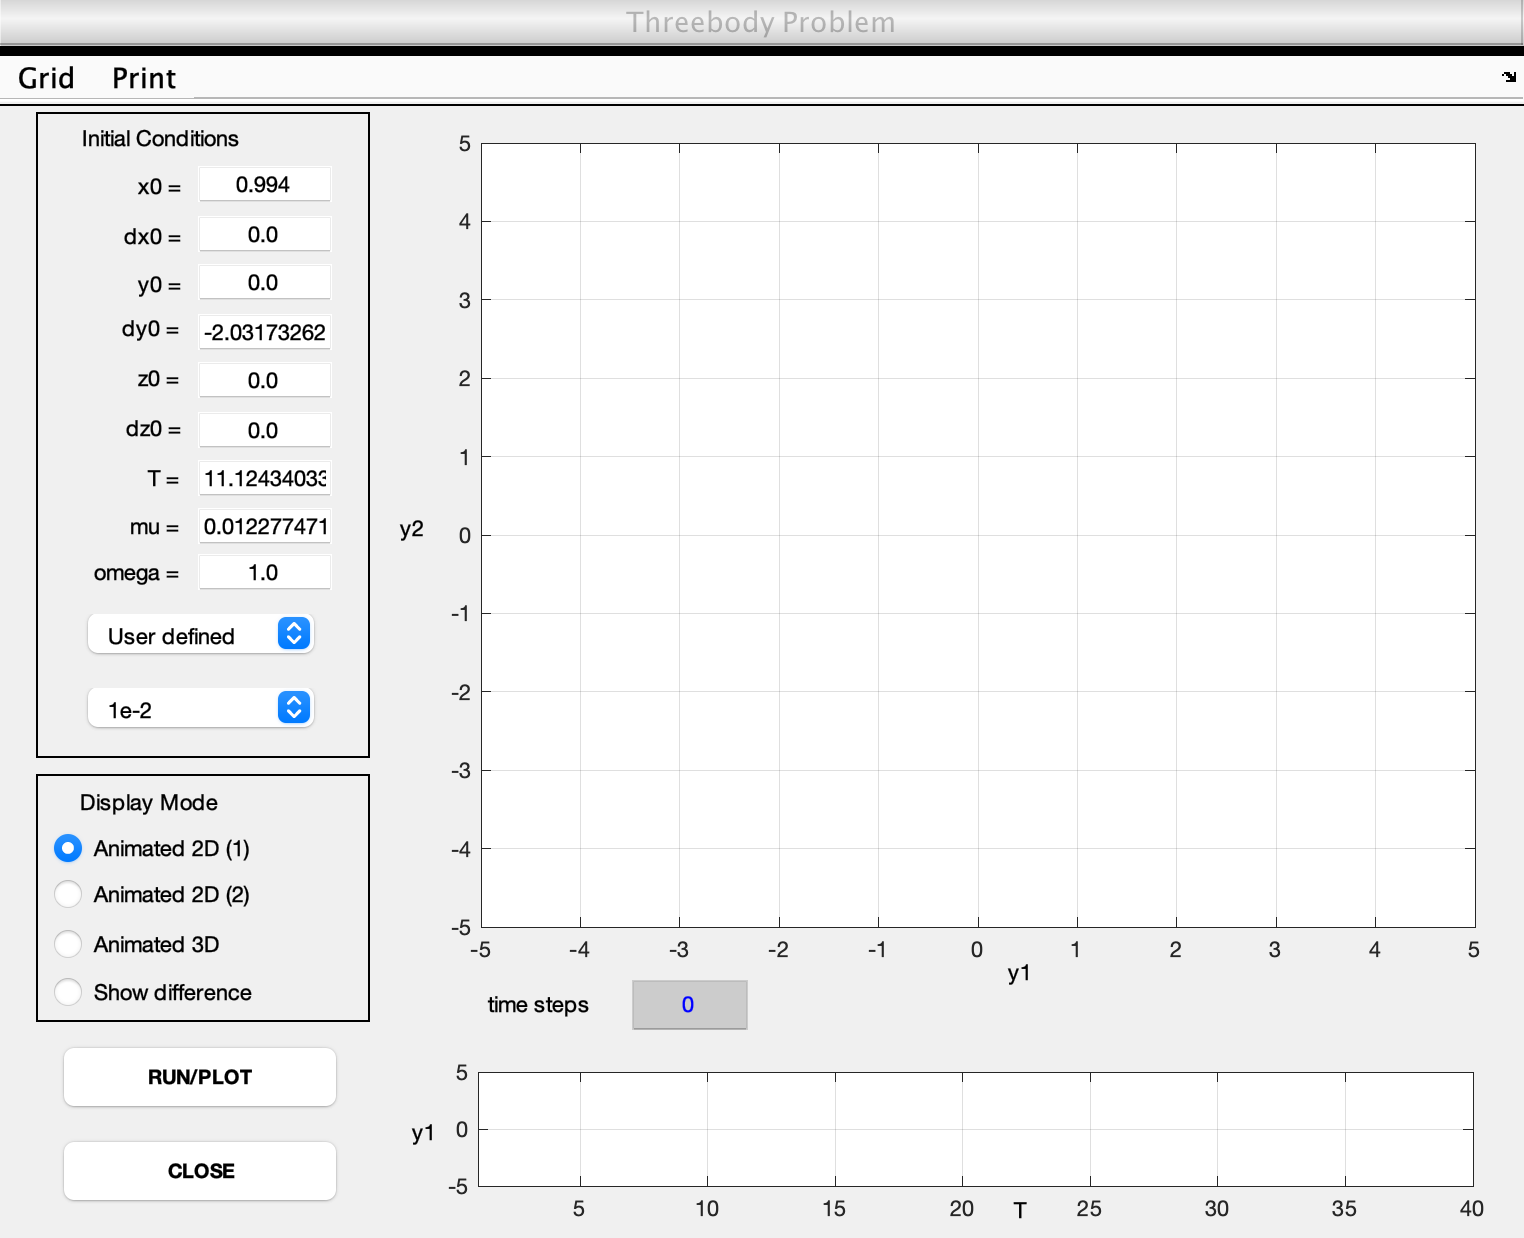

threebody

# Function

### f_stk(x) function

function y = f_stk(x)

% Y = F_STK(X)   Defines a piecewise continuous function.
%
%        { -sin(x)  x < 0
% f(x) = { x^2      0 <= x <= 1
%        { 1/x      x > 1
	
y = -sin(x).*(x<0);
y = y + x.^2.*(x>=0 & x<=1);
y = y + 1./x.*(x>1);
end


### n_ecke function

function n_ecke(m)

% N_ECKE(M)  Draw polygons with M edges in the domain
% defined by interval.

minEdges = 3;
maxEdges = 30;
interval = [0 10; 0 10];

for k = 1:m
	n = minEdges + floor(rand(1)*(maxEdges-minEdges));
	a = rand(1)*2*pi;
	b = linspace(a,2*pi+a,n+1);
	
	x = cos(b);
	y = sin(b);
	
	center = interval(:,1) + rand(2,1).*(interval(:,2)-interval(:,1));
	
	patch(x+center(1),y+center(2),rand(1,3));
	axis square;
end
end


### Euler function

function [t,y] = EULER(FUNC,t0,T,y0,n,var)

% solves the ODE given in FUNC with the
% explicit Euler method:
%
%  y(i+1) = y(i) + h * f(t(i),y(i))
%
% FUNC:     ODE to be solved
% [t0, T]: time interval in question
% y0:       initial value
% n:        number of time steps
% var:      variables for the ODE
%
% t:        time step vector
% y:        solution vector

t(1) = t0;
y(:,1) = y0;
h = (T-t0)/n;

for i = 1:n
    t(i+1) = t0 + i*h;
    y(:,i+1) = y(:,i) + h*FUNC(t(i),y(:,i),var);
end
end


### Linear pendulum mode

function [f] = LINEARPENDULUMODE(t,y,var)

% differential equations of the linearized pendulum
% 
% y(1):  displacement
% y(2):  velocity
% l   :  length of pendulum
% g   :  gravitational constant

l = var(1);
g = var(2);
f = [y(2); 
     -g/l*y(1)];
end


### Implicit Euler

function [t,y] = IMPR_EULER(FUNC,t0,T,y0,n,var)

% solves the ODE given in FUNC with the
% improved Euler method:
%
% FUNC:     ODE to be solved
% [t0, T]:  time interval in question
% y0:       initial value
% n:        number of time steps
% var:      variables for the ODE
%
% t:        time step vector
% y:        solution vector

t(1) = t0;
y(:,1) = y0;
h = (T-t0)/n;

for i = 1:n
    t(i+1) = t0 + i*h;
    ymid = y(:,i) + 0.5*h*FUNC(t(i),y(:,i),var);
    y(:,i+1) = y(:,i) + h*FUNC(t(i)+0.5*h,ymid,var);
end
end

### Fixed_point

function [fp, iter] = fixed_point(PHI, x0, TOL, Nmax)

% FIXED_POINT   locate the fixed point of an arbitrary function 
%               using general fixed_point iteration
%
%     calling sequence:
%             [fp, iter] = fixed_point (PHI, x0, TOL, Nmax)
%
%     inputs:
%             PHI     string containing name of m-file defining the
%                     iteration function
%             x0      initial approximation to location of fixed point
%             TOL     absolute error convergence tolerance
%             Nmax    maximum number of iterations to be performed
%
%     output:
%             fp      approximate value of fixed point
%             iter    number of iterations
%

iter = 1;
fp = x0;

while iter <= Nmax 
   fpold = fp;
   fp = PHI(fp);
   if abs(fp-fpold) < TOL		%stopping criterion
      disp(' ')
      disp(sprintf('The procedure was successful after %d iterations',iter))
      disp(sprintf('The root to the equation is %f',fp))
      return
   end
  iter = iter+1;
end

disp(' ')
disp(sprintf('The iteration did not converge within %d iterations',Nmax))
disp(sprintf('The last two iterates are %f and %f',fp,fpold))
end


### Runge Kuta 4 order

function [t ,y] = RK4class(FUNC,t0 ,tN,y0,N,var)
% Butcher−Scheme of the implemented Runge−Kutta−Method : 
%0    |
% 0.5 | 0.5
% 0.5 | 0   0.5
% 1   | 0    0   1
%−−−−−−−−−−−−−−−−−−−−−− 
%     | 1/6 2/6 2/6 1/6
%FUNC: ODE to be solved
%[t0 , tN]: time interval in question
%y0: initial value
% N:number of time steps
% var : variables for the ODE
%t :time step vector
%y: solution vector
t(1) = t0;
y(:,1) = y0;
h = (tN-t0)/N;
k = zeros(length(y0), 4);
for i=1:N
    t(i+1) = t0 + i*h;
    k(:,1) =FUNC(t(i), y(:,i),var);
    k(:,2) =FUNC(t(i) + 0.5*h, y(:,i)+0.5*h*k(:,1),var);
    k(:,3) =FUNC(t(i) + 0.5*h, y(:,i)+0.5*h*k(:,2),var);
    k (:,4)=FUNC(t(i) + h, y(:,i)+h*k(:,3),var);
    y(:,i+1) = y(:,i) + h * k * [1/6; 2/6; 2/6; 1/6];
end
end

### Test function

function [f] =RHSFUNC(t,y,var)
% right hand side function for test differential equation
var=0.5;
f = t^var;
end

### Runge Kuta second way

function [ynew,est ,k1new] = RK43(FUNC,told ,yold ,h,k1,var)
% FSAL embedded Runge−−Kutta method for step size control 
% with the Butcher scheme
%  0|
%0.5|0.5
%0.5| 0 0.5 %1|001
% 1 | 1/6 2/6 2/6 1/6
%−−−−−−−−−−−−−−−−−−−−−−−−−−−
%p=4|1/6 2/6 2/6 1/6  0
%p=3|1/6 2/6 2/6 0    1/6
%computation of the k_j

k(:,1) = k1;
k(:,2) = FUNC(told + 0.5*h, yold + 0.5*h*k(:,1), var);
k(:,3) = FUNC(told + 0.5*h, yold + 0.5*h*k(:,2), var);
k(:,4) = FUNC(told + h, yold + h*k(:,3), var);
k(:,5) = FUNC(told + h, yold + h*k(:,1:4)*[1/6; 2/6; 2/6; 1/6], var);
% save l a s t computation (FSAL) k1new = k(: ,5);
% computation of the new solution y (i+1)
ynew = yold + h * k * [1/6; 2/6; 2/6; 1/6; 0];
% computation of the comparison solution
yhat = yold + h * k * [1/6; 2/6; 2/6; 0; 1/6];
% error indicator
est = norm(ynew-yhat);
    if (~est)est=eps;
    end
end


function [t,y] = SOLVERK43(FUNC,t0,T,y0,var,tol ,h0,param)

%Solves the ODE with the right hand side FUNC
%by means of a FSAL−RK method and step size control
%Input: FUNC handle to the right hand side function 
% [ t0 ,T]: time interval
% y0: initial value at time t0 
% var: parameter for FUNC 
% tol: relative tolerance
% h0: initial step size
% param parameter for the step size control
% Output: t  vector with time steps
% y  matrix with solution vectors

if nargin < 8
    % default settings
    param = [1e-6; 1.0; 0.2; 2; 0.9];
end
if nargin < 7
    % default initial step size
    h0 = 0.1*(T-t0);
end
if nargin < 6
    % default tolerance
    tol = 1e-4;
end
% parameter for the step size control hmin = param(1);
hmax = param(2);
alphamin = param(3);
alphamax = param(4);
beta = param(5);
% consistency order p
order = 4;
% initialize the step size h = h0;
% initialize the time step vector tnow = t0;
t = [t0];
% initialize the solution matrix y = [y0];
% initialize the initial conditions yold = y0;
k1old = feval(FUNC,t,yold,var);
while (tnow < T) tnew = tnow + h;
    % RK4(3) method
    [ynew, est, k1] =RK43(FUNC, tnow, yold, h, k1old, var);
    % calculate new step size
    qh = est/(h*tol);
    alpha = max(alphamin ,qh^(-1/order )); 
    alpha = min(alphamax , alpha );
    h = max(beta*alpha*h, hmin);
    h = min([h,T-tnow,hmax]);
    if ((qh <= 1) | (h <= hmin))
        % accept the step

        yold = ynew; k1old = k1; tnow = tnew; t = [t tnow]; y = [y ynew];
    end 
end
end